# Actividad 5: Evaluación robot_2

- **Daniel Castillo López A01737357**

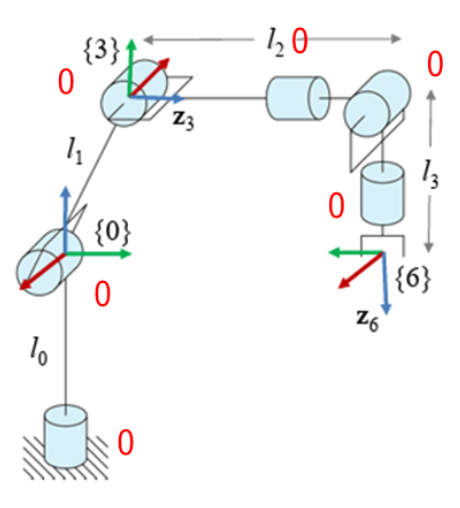

## Inicialización y Declaración de Variables

clear all
close all
clc

Declaramos los valores utilizado por las rotaciones y los desplazamientos que encontramos en nuestro robt, esto lo enfatizo debido a que en todas las articulaciones encontramos alguna rotación

syms th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) t d1 a2 a3 d4 l5 l6

Establecemos 6 vectores, donde establecera su tipo donde 0 es rotacional y también las coordenadas generalizadas

RP=[0 0 0 0 0 0];
Q= [th1, th2, th3, th4, th5, th6];
disp('Coordenadas generalizadas'); pretty (Q);

Coordenadas generalizadas
(th1(t), th2(t), th3(t), th4(t), th5(t), th6(t))



Lo mismo será para sus velocidades

Qp= diff(Q, t);
disp('Velocidades generalizadas'); pretty (Qp);

Velocidades generalizadas
/  d          d          d          d          d          d        \
| -- th1(t), -- th2(t), -- th3(t), -- th4(t), -- th5(t), -- th6(t) |
\ dt         dt         dt         dt         dt         dt        /



GDL= size(RP,2);
GDL_str= num2str(GDL);

## Cinemática Directa

La cinemática directa permite encontrar la posición del extremo del robot a partir de sus ángulos articulares, en base a la ayuda de tener una matriz de posición y de rotación

### Articulación 1

Como definimos en nuestra aarticulación, notamos una posición que seerá establecida por la rotación en la que presenta, esto ayudará a ver en  que posición podemos encontras la base y su cambio de posición con respecto a la articulación 2, nos deja en claro como el primer movimiento se realiza en el eje y a 90°

%definimos multiplicación
rotacion_z= [cos(th1)  -sin(th1)   0 ;
             sin(th1)   cos(th1)   0 ;
               0            0      1];

y_transf= [ 0  0  1;   %y +90
            0  1  0;
           -1  0  0];
 
transfor_1= rotacion_z*y_transf;
disp(transfor_1);

$$\left(\begin{array}{ccc} 0 & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ -1 & 0 & 0 \end{array}\right)$$

%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2
P(:,:,1)= [0;0;d1];

%Matriz de rotación de la junta 1 a 2
R(:,:,1)= transfor_1;

### Articulación 2

Al no presentar algun cambio con respecto a la articulación 3 , se le designa la matriz de rotación en z debido a su posición 

%Articulación 2 a Articulación 3
%Posición de la articulación 2 a 3
P(:,:,2)= [a2*cos(th2);a2*sin(th2);0];

%Matriz de rotación de la junta 2 a 3
R(:,:,2)= [cos(th2)  -sin(th2)   0 ;
           sin(th2)   cos(th2)   0 ;
           0          0          1];

### Articulación 3 

rotacion_z= [cos(th1)  -sin(th1)   0 ;
             sin(th1)   cos(th1)   0 ;
               0            0      1];

x_transf= [1  0  0;   %x -90
           0  0  1;
           0  -1  0];
 
transfor_3= rotacion_z*x_transf;
disp(transfor_3);

$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & -1 & 0 \end{array}\right)$$


%Posición de la articulación 3 respecto a 2
P(:,:,3)= [a3*cos(th3);a3*sin(th3);0];

%Matriz de rotación de la junta 3 respecto a 2
R(:,:,3)= (transfor_3);

### Articulación 4

rotacion_z= [cos(th1)  -sin(th1)   0 ;
             sin(th1)   cos(th1)   0 ;
               0            0      1];

x_transf= [1  0  0;   %x +90
           0  0 -1;
           0  1  0];
 
transfor_4= rotacion_z*x_transf;
disp(transfor_4);

$$\left(\begin{array}{ccc} \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & \sin\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & -\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ 0 & 1 & 0 \end{array}\right)$$

%Posición de la articulación 3 respecto a 2
P(:,:,4)= [0;0;-d4];

%Matriz de rotación de la junta 3 respecto a 2
R(:,:,4)= transfor_4;

### Articulación 5

rotacion_z= [cos(th1)  -sin(th1)   0 ;
             sin(th1)   cos(th1)   0 ;
               0            0      1];
y_transf= [ 0  0  -1;   %y -90
            0  1  0;
           1  0  0];
 
transfor_5= rotacion_z*y_transf;
%Posición de la articulación 3 respecto a 2
P(:,:,5)= [l5*cos(th5);l5*sin(th5);0];

%Matriz de rotación de la junta 3 respecto a 2
R(:,:,5)= transfor_5;

### Articulación 6

%Posición de la articulación 3 respecto a 2
P(:,:,6)= [0;0;0];

%Matriz de rotación de la junta 3 respecto a 2
R(:,:,6)=   [cos(th6) -sin(th6)  0;
             sin(th6)  cos(th6)  0;
               0         0       1];

Las matrices locales y globales de transformación, nos demuestran la estructura de orientación y posición, enfatizando en los cambios del extremo en nuestro robot con respecto a su marco de referencia inercial

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL);

%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 

En nuestro bucle for nos desarrolla el calculo de las matrices locales, las que nos especifican la posición y orienteación con respecto a la articulación anterior, como las globales, que recorren la posición y orientación del inicio y del final

for i = 1:GDL
    i_str= num2str(i);

    %Locales
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    disp(strcat('Matriz de Transformación local A', i_str)); pretty(A(:,:,i));
    disp('    ');

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    T(:,:,i)= simplify(T(:,:,i));
    disp(strcat('Matriz de Transformación global T', i_str)); pretty(T(:,:,i));
    disp('    ');

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

## Cálculo del jacobiano lineal de forma diferencial

El Jacobiano diferencial es obtenido mediante derivadas parciales de la posición.

%Derivadas parciales de x respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
Jv14= functionalDerivative(PO(1,1,GDL), th4);
Jv15= functionalDerivative(PO(1,1,GDL), th5);
Jv16= functionalDerivative(PO(1,1,GDL), th6);

%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
Jv24= functionalDerivative(PO(2,1,GDL), th4);
Jv25= functionalDerivative(PO(2,1,GDL), th5);
Jv26= functionalDerivative(PO(2,1,GDL), th6);

%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);
Jv34= functionalDerivative(PO(3,1,GDL), th4);
Jv35= functionalDerivative(PO(3,1,GDL), th5);
Jv36= functionalDerivative(PO(3,1,GDL), th6);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13 Jv14 Jv15 Jv16;
               Jv21 Jv22 Jv23 Jv24 Jv25 Jv26;
               Jv31 Jv32 Jv33 Jv34 Jv35 Jv36]);
disp('Jacobiano lineal obtenido de forma diferencial'); pretty(jv_d);

## Cálculo del jacobiano lineal y angular de forma analítica

%Inicializamos jacobianos analíticos (lineal y angular)
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Para articulaciones rotacionales, la velocidad lineal se obtiene mediante el producto cruzado entre el eje de rotación y la diferencia de posiciones, mientras que la velocidad angular se toma directamente del eje de rotación. Si no hay una matriz de rotación previa, se usa la identidad y la posición inicial. Para articulaciones prismáticas, la velocidad lineal es el eje de desplazamiento, y la angular es cero, ya que no hay rotación.

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     
     elseif RP(k)==1 %Casos: articulación prismática
        %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Despliegue
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica'); pretty (Jv_a);
disp('Jacobiano ángular obtenido de forma analítica'); pretty(Jw_a);
V=simplify (Jv_a*Qp');
disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); pretty(V);
W=simplify (Jw_a*Qp');
disp('Velocidad angular obtenida mediante el Jacobiano angular'); pretty(W)